# Testing all images in DB to our dataset in DB1

clear TNM034
clear
clf
clc

## DB1 Testing

files=dir('./DB1/*.jpg');
files =  {files.name};

% Test all files in a dataset against our dataset based on DB1
for file = files
    path = './DB1/' + string(file);
    im = imread(path);
    
    im = im * 1.3;
%     im = imrotate(im,5,'bilinear','crop');
%     im = imresize(im,0.9);
    
    [id,value] = TNM034(im);
    fprintf('%s, %i, %.4f \n', string(file), id, value);
end

Building dataset:
Creating image matrix
Image: db1_01.jpg 
Image: db1_02.jpg 
Image: db1_03.jpg 
Image: db1_04.jpg 
Image: db1_05.jpg 
Image: db1_06.jpg 
Image: db1_07.jpg 
Image: db1_08.jpg 
Image: db1_09.jpg 
Image: db1_10.jpg 
Image: db1_11.jpg 
Image: db1_12.jpg 
Image: db1_13.jpg 
Image: db1_14.jpg 
Image: db1_15.jpg 
Image: db1_16.jpg 
Creating mean face
Creating weights


db1_01.jpg, 1, 8.0131 
db1_02.jpg, 2, 9.9219 
db1_03.jpg, 3, 11.5739 
db1_04.jpg, 4, 7.3119 
db1_05.jpg, 5, 6.4624 
db1_06.jpg, 6, 4.9300 
db1_07.jpg, 7, 6.0659 
db1_08.jpg, 0, 28.6736 
db1_09.jpg, 0, 27.2327 
db1_10.jpg, 0, 20.6845 
db1_11.jpg, 11, 11.4093 
db1_12.jpg, 12, 11.7041 
db1_13.jpg, 0, 20.4265 
db1_14.jpg, 0, 26.9902 
db1_15.jpg, 15, 10.0064 
db1_16.jpg, 16, 3.4776 


## DB0 Testing

clear TNM034
clear
clf
clc
files=dir('./DB1/*.jpg');
files =  {files.name};


count = 0;
clear value
for file = files
        path = './DB1/' + string(file);
        im = imread(path);
        
        im = im * 1.3;
%       im = imrotate(im,20,'bilinear','crop');
%         im = imresize(im,0.7);
    
        [id, value] = TNM034(im);
        if id > 0
            count = count + 1;
        end
        fprintf('%s, %i, %.4f \n', string(file), id, value);
end

Building dataset:
Creating image matrix
Image: db1_01.jpg 
Image: db1_02.jpg 
Image: db1_03.jpg 
Image: db1_04.jpg 
Image: db1_05.jpg 
Image: db1_06.jpg 
Image: db1_07.jpg 
Image: db1_08.jpg 
Image: db1_09.jpg 
Image: db1_10.jpg 
Image: db1_11.jpg 
Image: db1_12.jpg 
Image: db1_13.jpg 
Image: db1_14.jpg 
Image: db1_15.jpg 
Image: db1_16.jpg 
Creating mean face
Creating weights


db1_01.jpg, 1, 8.0131 
db1_02.jpg, 2, 9.9219 
db1_03.jpg, 3, 11.5739 
db1_04.jpg, 4, 7.3119 
db1_05.jpg, 5, 6.4624 
db1_06.jpg, 6, 4.9300 
db1_07.jpg, 7, 6.0659 
db1_08.jpg, 0, 28.6736 
db1_09.jpg, 0, 27.2327 
db1_10.jpg, 0, 20.6845 
db1_11.jpg, 11, 11.4093 
db1_12.jpg, 12, 11.7041 
db1_13.jpg, 0, 20.4265 
db1_14.jpg, 0, 26.9902 
db1_15.jpg, 15, 10.0064 
db1_16.jpg, 16, 3.4776 


count

count = 11



% Test all files in a dataset against our dataset based on DB1
j_count = 0;
id_succsess = zeros(1,13)

id_succsess =      0     0     0     0     0     0     0     0     0     0     0     0     0


for j = 0.7:0.05:1.3
    j_count = j_count + 1;
    i = 0;
    for file = files
        i = i+1;
        path = './DB1/' + string(file);
        im = imread(path);
        
%         im = im * j;
      im = imrotate(im,-20,'bilinear','crop');
%         im = imresize(im,0.7);
    
        [id(i), ~] = TNM034(im);
        id(i) = id(i) > 0;
%       fprintf('%s, %i, %.4f \n', string(file), id, value);
    end
    id_succsess(1,j_count) = sum(id);
end

title('Korrekt antal klassificerade bilder mot ljusintensitet')
xlabel('Ljusintensitetsfaktor')
ylabel('Antal korrekt klassificerade bilder')
plot((0.7:0.05:1.3),id_succsess)


files=dir('./DB1/*.jpg');
files =  {files.name};

% Test all files in a dataset against our dataset based on DB1
success = 0;
attempts = 0;
for j = 1:50
    for file = files
        attempts = attempts+1;
        path = './DB1/' + string(file);
        im = imread(path);
        
        r1 = 0.7 + (1.3-0.7)*rand(1);
        r2 = -5 + (5-(-5))*rand(1);
        r3 = 0.9 + (1.1-0.9)*rand(1);
        
        im = im * r1;
        im = imrotate(im,r2,'bilinear','crop');
        im = imresize(im,r3);
    
        [id, value] = TNM034(im);
        if id ~= 0
            success = success + 1;
        end
      fprintf('%s, %i, %.4f \n', string(file), id, value);
    end
end

Building dataset:
Creating image matrix
Image: db1_01.jpg 
Image: db1_02.jpg 
Image: db1_03.jpg 
Image: db1_04.jpg 
Image: db1_05.jpg 
Image: db1_06.jpg 
Image: db1_07.jpg 
Image: db1_08.jpg 
Image: db1_09.jpg 
Image: db1_10.jpg 
Image: db1_11.jpg 
Image: db1_12.jpg 
Image: db1_13.jpg 
Image: db1_14.jpg 
Image: db1_15.jpg 
Image: db1_16.jpg 
Creating mean face
Creating weights


db1_01.jpg, 1, 6.2562 
db1_02.jpg, 2, 7.8217 
db1_03.jpg, 3, 2.5970 
db1_04.jpg, 4, 1.2417 
db1_05.jpg, 5, 5.9001 
db1_06.jpg, 6, 1.4279 
db1_07.jpg, 7, 7.6275 
db1_08.jpg, 8, 14.8183 
db1_09.jpg, 9, 15.0444 
db1_10.jpg, 10, 4.1590 
db1_11.jpg, 11, 1.4411 
db1_12.jpg, 12, 1.5875 
db1_13.jpg, 13, 10.4246 
db1_14.jpg, 14, 4.7704 
db1_15.jpg, 15, 1.2044 
db1_16.jpg, 16, 1.5545 
db1_01.jpg, 1, 6.8108 
db1_02.jpg, 2, 6.2537 
db1_03.jpg, 3, 4.1973 
db1_04.jpg, 4, 4.8735 


Crop Image: Can not find eyes
Error: cropImage returned no eyes...


db1_05.jpg, 0, 0.0000 
db1_06.jpg, 6, 1.1634 
db1_07.jpg, 7, 6.9636 
db1_08.jpg, 8, 17.0172 
db1_09.jpg, 9, 13.9524 
db1_10.jpg, 10, 6.2466 
db1_11.jpg, 11, 7.4171 
db1_12.jpg, 12, 2.0705 
db1_13.jpg, 13, 10.8535 
db1_14.jpg, 14, 6.6417 
db1_15.jpg, 15, 2.7189 
db1_16.jpg, 16, 1.9170 
db1_01.jpg, 1, 5.4252 
db1_02.jpg, 2, 7.2646 
db1_03.jpg, 3, 4.6370 
db1_04.jpg, 4, 0.1217 
db1_05.jpg, 5, 4.9563 
db1_06.jpg, 6, 0.8121 
db1_07.jpg, 7, 3.1280 
db1_08.jpg, 8, 14.5173 
db1_09.jpg, 9, 13.0043 
db1_10.jpg, 10, 3.9936 
db1_11.jpg, 11, 2.0478 
db1_12.jpg, 12, 1.7030 
db1_13.jpg, 13, 10.8859 
db1_14.jpg, 14, 5.3137 
db1_15.jpg, 15, 3.3395 
db1_16.jpg, 16, 1.3649 
db1_01.jpg, 1, 6.6250 
db1_02.jpg, 2, 6.8046 
db1_03.jpg, 3, 2.8715 
db1_04.jpg, 4, 6.2301 
db1_05.jpg, 5, 0.9149 
db1_06.jpg, 6, 1.9912 
db1_07.jpg, 7, 5.1859 
db1_08.jpg, 0, 29.9221 
db1_09.jpg, 9, 13.8662 
db1_10.jpg, 10, 6.4774 
db1_11.jpg, 11, 8.3342 
db1_12.jpg, 12, 1.5997 
db1_13.jpg, 0, 21.8933 
db1_14.jpg, 14, 0.4693 
db1_15.

fprintf('Success rate: %.4f \n', success/attempts);

Success rate: 0.9700 


## Single file testing

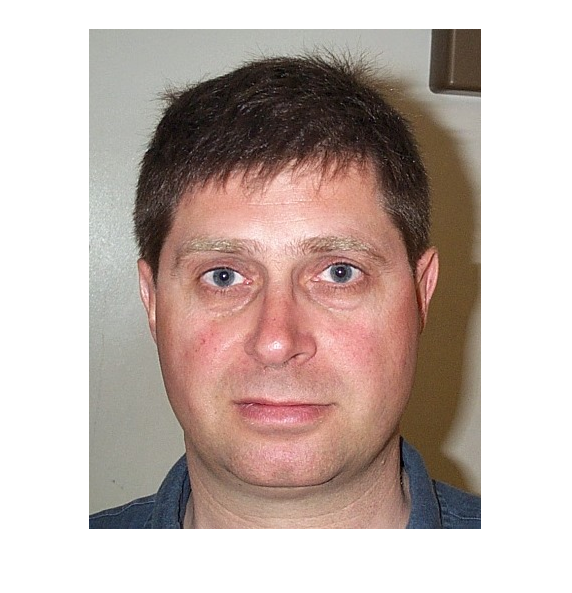

im = imread('./DB1/db1_01.jpg');
% im = imrotate(im,5,'bilinear','crop');
% im = im * 1.3;
imshow(im)

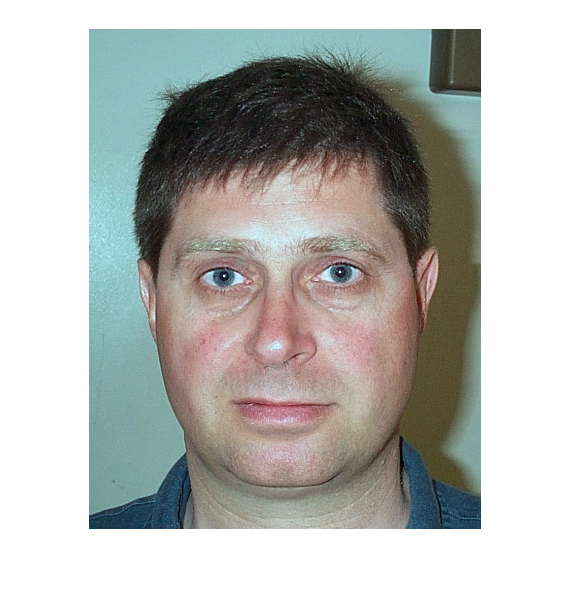

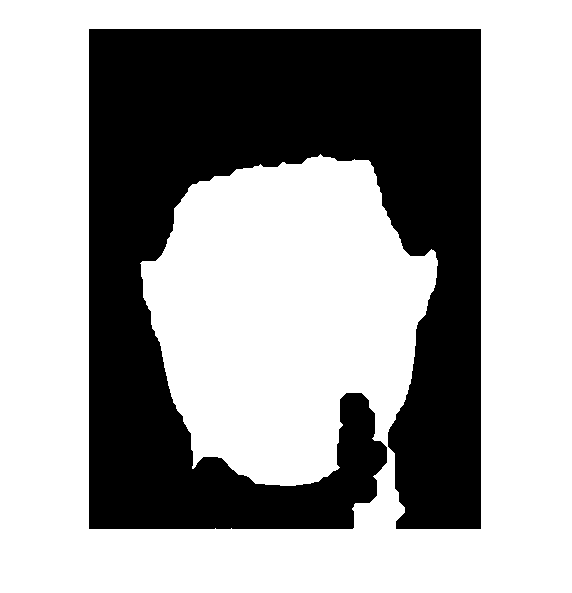

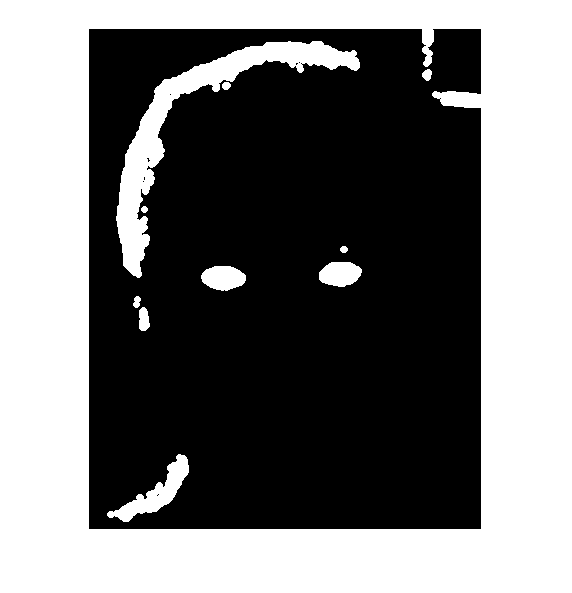

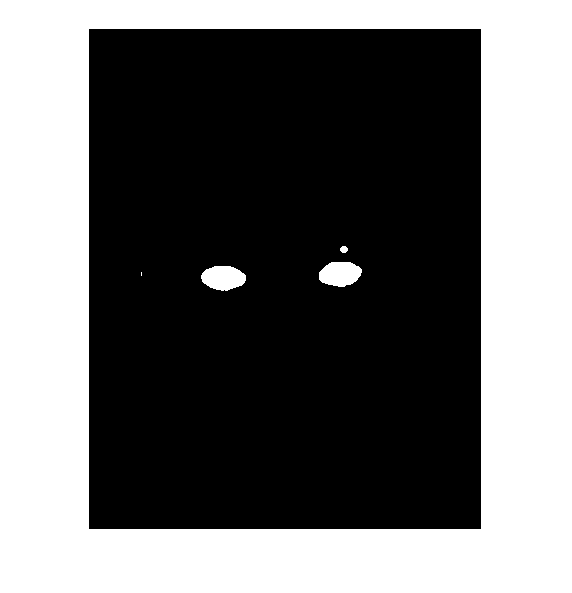

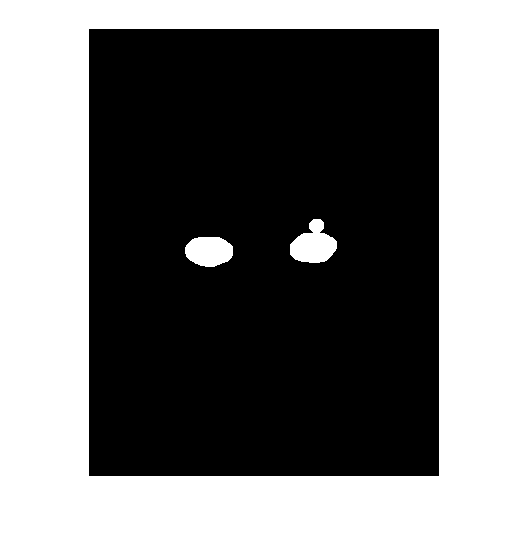

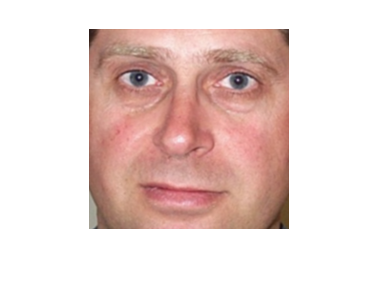

id = 1

value = 1.2271e-14

[id,value] = TNM034(im)

## Misc testing

RGB = imread('./DB2/bl_01.jpg');
im = RGB* 1.3;
imshow(im)

im = imrotate(RGB,5,'bilinear','crop');
im = imresize(im,1.1);
imshow(im)

im = cropImage(RGB)
im = whitePatch(im);
im = normalizeRGBImage(im);
imshow(im)
im = faceMask(im);
imshow(im)

